# Additional Work

close all; clear; clc;

## Read the WAV file

% Read the WAV file
[y, fs] = audioread('input/Sample 01.wav');
N = length(y);
tx = linspace(0, N/fs, N);

## FFT-Fast Fourier Transformation

% Compute FFT
fx = linspace(0, fs, N);
Y = fft(y);

## Plot Input Signal

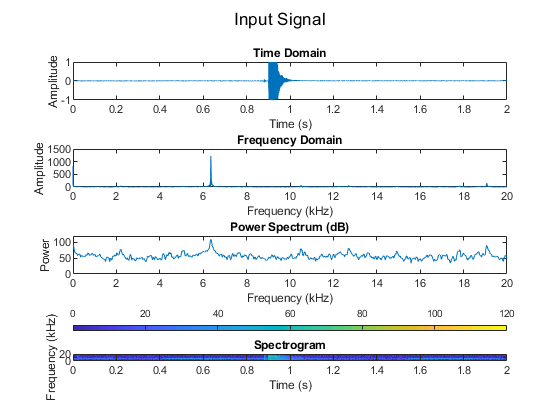

plotAllDomains(y,tx)
sgtitle('Input Signal');

## Implement Different kind of denoise techniques

% Smoothed signals
y_movmean   = smoothdata(y,'movmean');      % Moving mean
y_movmedian = smoothdata(y,'movmedian');    % Moving median    
y_gaussian  = smoothdata(y,'gaussian');     % Gaussian
y_lowess    = smoothdata(y,'lowess');       % Linear regression
y_loess     = smoothdata(y,'loess');        % Quadratic regression
y_rlowess   = smoothdata(y,'rlowess');      % Robust linear regression
y_rloess    = smoothdata(y,'rloess');       % Robust quadratic regression
y_sgolay    = smoothdata(y,'sgolay');       % Savitzky-Golay

% Filtered signals
y_lowpass   = lowpass(y,10000,fs,'Steepness',0.85,'StopbandAttenuation',60);            % Lowpass butterworth filter
y_highpass  = highpass(y,2000,fs,'Steepness',0.85,'StopbandAttenuation',60);            % Highpass butterworth filter
y_bandpass  = bandpass(y,[2000 10000],fs,'Steepness',0.85,'StopbandAttenuation',60);    % Bandpass butterworth filter
y_bandstop  = bandstop(y,[6000 7000],fs,'Steepness',0.85,'StopbandAttenuation',60);     % Bandstop butterworth filter

% Custom Low Amplitude Frequency Filter / Spectral Subtraction
Y_lowamp = Y;
noise_level = 500;
for i = 1:N
  if abs(Y_lowamp(i)) < noise_level
    Y_lowamp(i) = 0;  % We can change this logic to anything
  end
end
y_lowamp = ifft(Y_lowamp);


% Custom High Amplitude Frequency Filter / Spectral Subtraction
Y_highamp = Y;
noise_level = 500;
for i = 1:N
  if abs(Y_highamp(i)) > noise_level
    Y_highamp(i) = 0;  % We can change this logic to anything
  end
end
y_highamp = ifft(Y_highamp);

% Adaptive thresholding based on local mean
window_size = 50; % Adjust this value based on your signal characteristics
Y_thresholding = zeros(size(Y));

for i = 1:N
    start_index = max(1, i - window_size);
    end_index = min(N, i + window_size);
    local_mean = mean(abs(Y(start_index:end_index)));
    
    if abs(Y(i)) > local_mean
        Y_thresholding(i) = Y(i);
    else
        Y_thresholding(i) = 0; % Zero out noise
    end
end
y_thresholding = ifft(Y_thresholding);


% Custom filters
% Brick Wall filter / bandpass
Y_cbandpass = zeros(size(Y));
cutoffLower = 6250;
cutoffUpper = 6500;
for i = 1:N
    if cutoffLower < fx(i) &&  fx(i) < cutoffUpper
        Y_cbandpass(i) = Y(i);
    else
        Y_cbandpass(i) = 0;
    end   
end
y_cbandpass = ifft(Y_cbandpass);

% Brick Wall filter /  highpass filter
Y_chighpass = zeros(size(Y));
cutoff = 10000;
for i = 1:N
    if fx(i) < cutoff
        Y_chighpass(i) = 0;
    else
        Y_chighpass(i) = Y(i);
    end   
end
y_chighpass = ifft(Y_chighpass);


% % Spectral Subtraction
% noise_level = 0.1; % Adjust noise level as needed
% spectrum_subtracted = max(0, abs(Y) - noise_level);
% 
% % Frequency Domain Averaging
% num_segments = 10; % Adjust the number of segments as needed
% segment_size = floor(N/num_segments);
% averaged_spectrum = zeros(size(spectrum));
% for i = 1:num_segments
%     start_idx = (i-1) * segment_size + 1;
%     end_idx = min(i * segment_size, N);
%     averaged_spectrum(start_idx:end_idx) = mean(spectrum(start_idx:end_idx));
% end
% 
% % Homomorphic Filtering
% alpha = 1; % Adjust alpha as needed
% homomorphic_spectrum = exp(alpha * log(abs(spectrum)));
% 
% % Harmonic Analysis
% harmonic_multiplier = 2; % Adjust harmonic multiplier as needed
% harmonic_spectrum = zeros(size(spectrum));
% harmonic_spectrum(harmonic_multiplier * indexOfMaxValue) = spectrum(indexOfMaxValue);

plotAllDomains(y_cbandpass,tx)

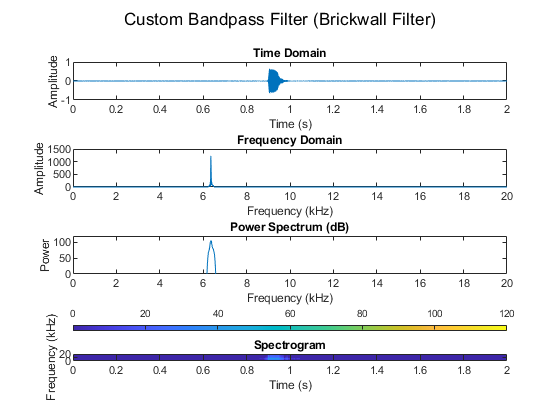

sgtitle('Custom Bandpass Filter (Brickwall Filter)');

audiowrite('export/input.wav', abs(y), fs);
audiowrite('export/movmean.wav', abs(y_movmean), fs);
audiowrite('export/movmedian.wav', abs(y_movmedian), fs);
audiowrite('export/gaussian.wav', abs(y_gaussian), fs);
audiowrite('export/lowess.wav', abs(y_lowess), fs);
audiowrite('export/loess.wav', abs(y_loess), fs);
audiowrite('export/rlowess.wav', abs(y_rlowess), fs);
audiowrite('export/rloess.wav', abs(y_rloess), fs);
audiowrite('export/sgolay.wav', abs(y_sgolay), fs);

audiowrite('export/lowpass.wav', abs(y_lowpass), fs);

audiowrite('export/highpass.wav', abs(y_highpass), fs);

audiowrite('export/bandpass.wav', abs(y_bandpass), fs);

audiowrite('export/bandstop.wav', abs(y_bandstop), fs);
audiowrite('export/cbandpass.wav', abs(y_cbandpass), fs);
audiowrite('export/chighpass.wav', abs(y_chighpass), fs);

audiowrite('export/highamp.wav', abs(y_highamp), fs);

audiowrite('export/lowamp.wav', abs(y_lowamp), fs);

audiowrite('export/thresholding.wav', abs(y_thresholding), fs);

function plotAllDomains(data, timeValues)
    % Parameters
    timeLimits = [0 2]; % seconds 
    frequencyLimits = [0 20]; % kHz
    decibelLimits = [0 120]; %dB
    amplitudeLimit = [0 1500];

    % Plot time domain
    subplot(4,1,1);
    plot(timeValues, data);
    xlim(timeLimits)
    ylim([-1 1])
    title('Time Domain');
    xlabel('Time (s)');
    ylabel('Amplitude');

    % Plot frequency domain
    subplot(4,1,2);
    fftData = fft(data);
    freqValues = linspace(0, 1/(2*(timeValues(2)-timeValues(1))), length(fftData)/2);
    plot(freqValues/1000, abs(fftData(1:length(freqValues))));
    xlim(frequencyLimits)
    ylim(amplitudeLimit)
    title('Frequency Domain');
    xlabel('Frequency (kHz)');
    ylabel('Amplitude');

    % My Custom power spectrum 
    subplot(4,1,3);
    minIdx = timeValues >= timeLimits(1);
    maxIdx = timeValues <= timeLimits(2);
    data_ROI = data(minIdx & maxIdx);
    timeValues_ROI = timeValues(minIdx & maxIdx);
    [Pdata_ROI, Fdata_ROI] = pspectrum(data_ROI, timeValues_ROI, 'FrequencyLimits', frequencyLimits*1000);
    plot(Fdata_ROI/1000, 12*log10((Pdata_ROI)/10e-12)); % don't think this is a standard equation. Nope this is made up one
    

    
    % using standard equation
%     refAmplitude = 10e-2;
%     plot(freqValues/1000, 20*log10(abs(fftData(1:length(freqValues)))/refAmplitude));
    
    xlim(frequencyLimits)
    ylim(decibelLimits)
    title('Power Spectrum (dB)');
    xlabel('Frequency (kHz)');
    ylabel('Power');

    % Plot spectrogram with color bar at the top
    subplot(4,1,4);
    spectrogram(data*1000000, hamming(256), 250, 256, 1/(timeValues(2)-timeValues(1)), 'yaxis');   
    colorbar('off');
    colorbar('Location', 'northoutside');
    caxis(decibelLimits);
    xlim(timeLimits)
    ylim(frequencyLimits)
    title('Spectrogram');
    xlabel('Time (s)');
    ylabel('Frequency (kHz)');
    
    % Adjust subplot layout
    sgtitle('Time, Frequency, Power Spectrum (dB), and Spectrogram');
end